clc;

r_earth = 6371000; % unit = m
G = 6.6743 * 10e-11;

% coordinates of satellite
orbit_gracefo1 = importdata("E:/lhsPrograms/gracefo_dataset/gracefo_1B_2020-07-02_RL04.ascii.noLRI/GNV1B_2020-07-02_C_04.txt", " ", 148);
orbit_gracefo2 = importdata("E:/lhsPrograms/gracefo_dataset/gracefo_1B_2020-07-02_RL04.ascii.noLRI/GNV1B_2020-07-02_D_04.txt", " ", 148);
coor_sate1 = orbit_gracefo1.data(2548: 5378, 1: 3);
coor_sate2 = orbit_gracefo2.data(2548: 5378, 1: 3);

% coordinates of sources
s_lat = linspace(-0.45*5, 0.45*5, 5);
s_lon = linspace(18.35, 19.45, 5);
s_hgt = linspace(-1, 0, 5);
s_mas = 100e3*100e3 * 10 * 1000 / 125 * ones(125, 1); % unit = kg

s_coor = [];
for i = 1: 5
    for j = 1: 5
        for k = 1: 5
            s_coor = [s_coor; [s_lat(i), s_lon(j), s_hgt(k)]];
        end
    end
end
writematrix(s_coor, "../output/coordinates_sources_syn.txt");

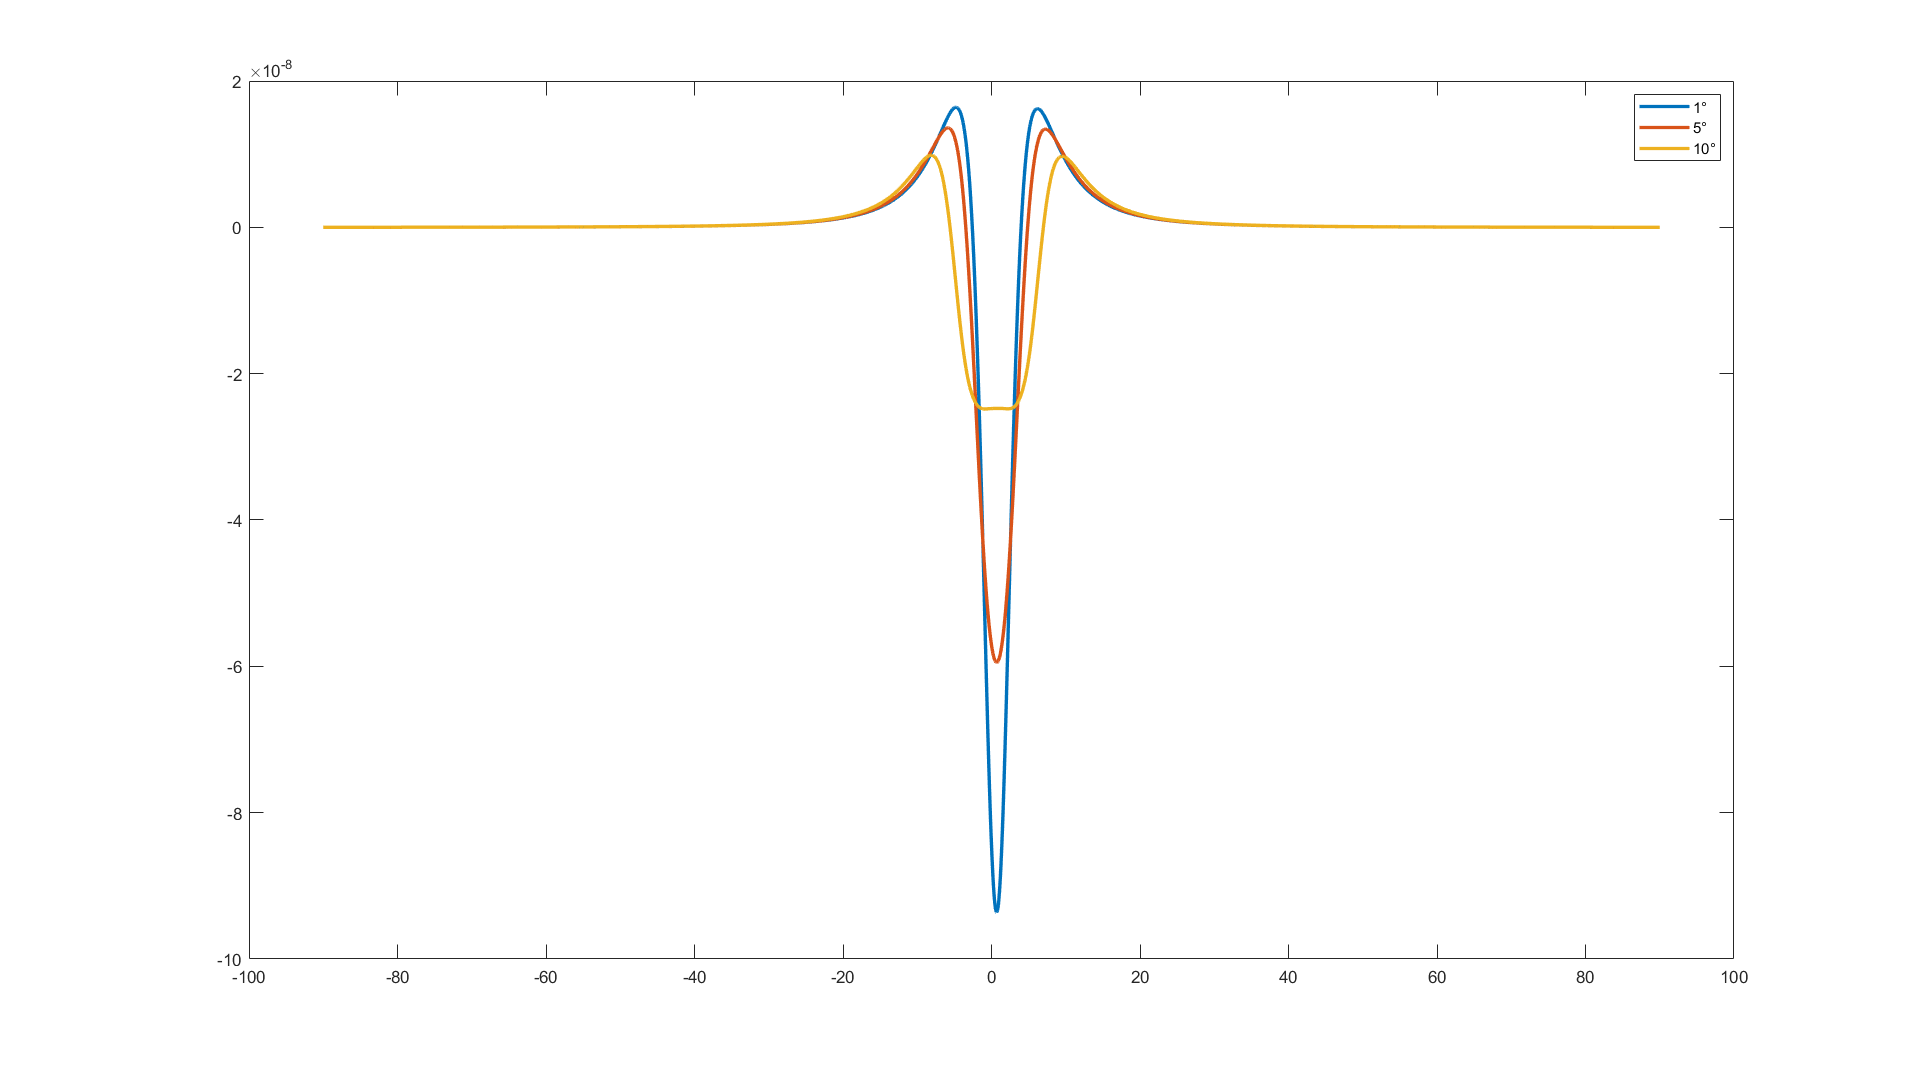

s_coor_1 = importdata("../output/coordinates_sources_syn_xyz.txt");
s_coor = s_coor_1;
% compute the acc
los = coor_sate2(:, 1: 3) - coor_sate1(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
acc_rela = zeros(length(coor_sate1), 3);
acc_sate1 = zeros(length(coor_sate1), 3);
lgd = zeros(length(coor_sate1), 1);
for i = 1: length(coor_sate1)
    f = zeros(3, length(s_mas));
    f1 = zeros(3, length(s_mas));
    for j = 1: length(s_mas)
        pit1 = coor_sate1(i, :) - s_coor(j, :);
        pit2 = coor_sate2(i, :) - s_coor(j, :);
        dis1 = sqrt(sum(pit1.^2, 2));
        dis2 = sqrt(sum(pit2.^2, 2));
        f(:, j) = pit1 / dis1^3 - pit2 / dis2^3;
        f1(:, j) = pit1 / dis1^3;
    end
    acc_sate1(i, :) = G * f1 * s_mas;
    acc_rela(i, :) = G * f * s_mas;
    lgd(i) = dot(acc_rela(i, :), los(i, :));
end
lgd_5 = lgd;
new_figure;
plot(linspace(-90, 90, length(lgd_1)), lgd_1, "LineWidth", 2); hold on
plot(linspace(-90, 90, length(lgd_1)), lgd_5, "LineWidth", 2); hold on
plot(linspace(-90, 90, length(lgd_3)), lgd_10, "LineWidth", 2); hold on
legend(["1°", "5°", "10°"])

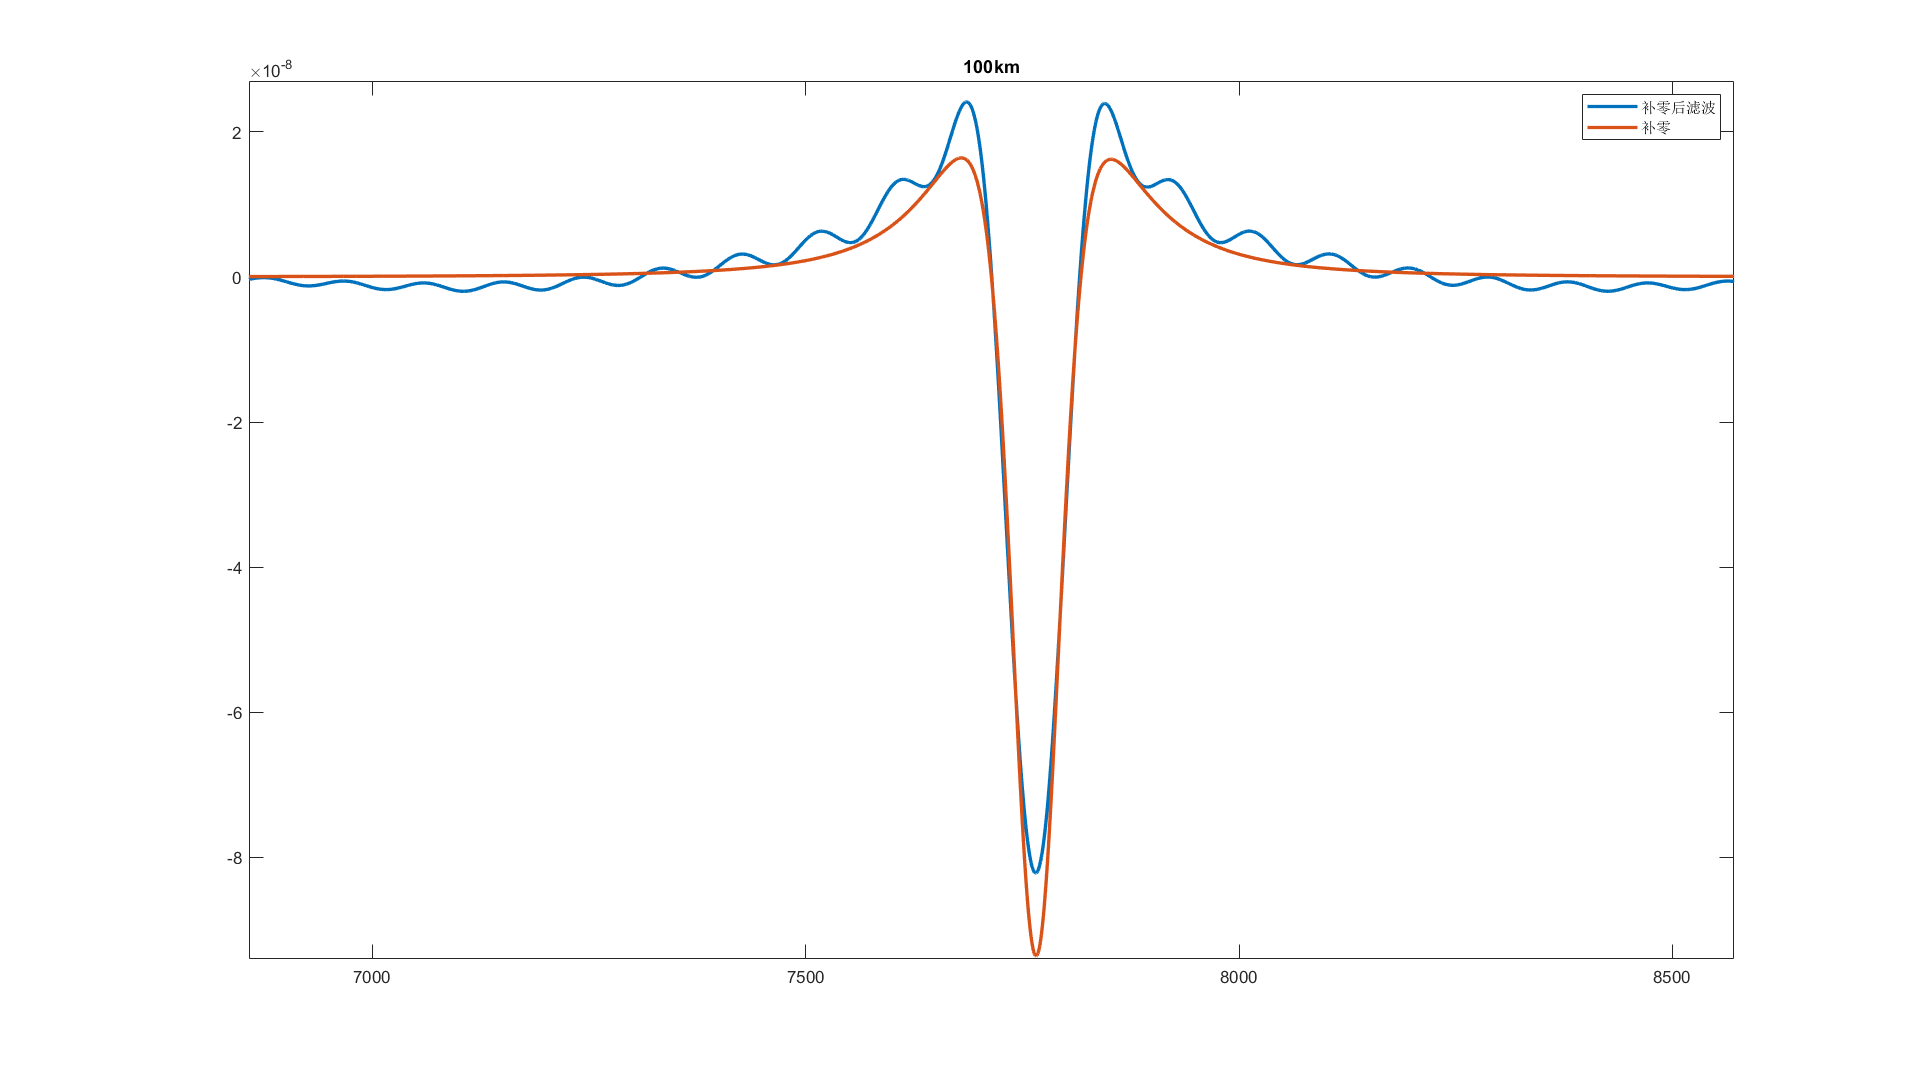

lgd_1_append = [zeros(10000, 1); lgd_1; zeros(10000, 1)];
lgd_filtered = filter_pdfree(Num1, lgd_1_append);
new_figure;
plot(lgd_filtered, "LineWidth", 2); hold on
plot(match_filter(Num1, lgd_1_append), "LineWidth", 2)
legend("补零后滤波", "补零")
title("100km")


new_figure;
fft_plot(lgd_1, 1, "m/s^2"); hold on;

fft_plot(lgd_1_append, 1, "m/s^2"); hold on;

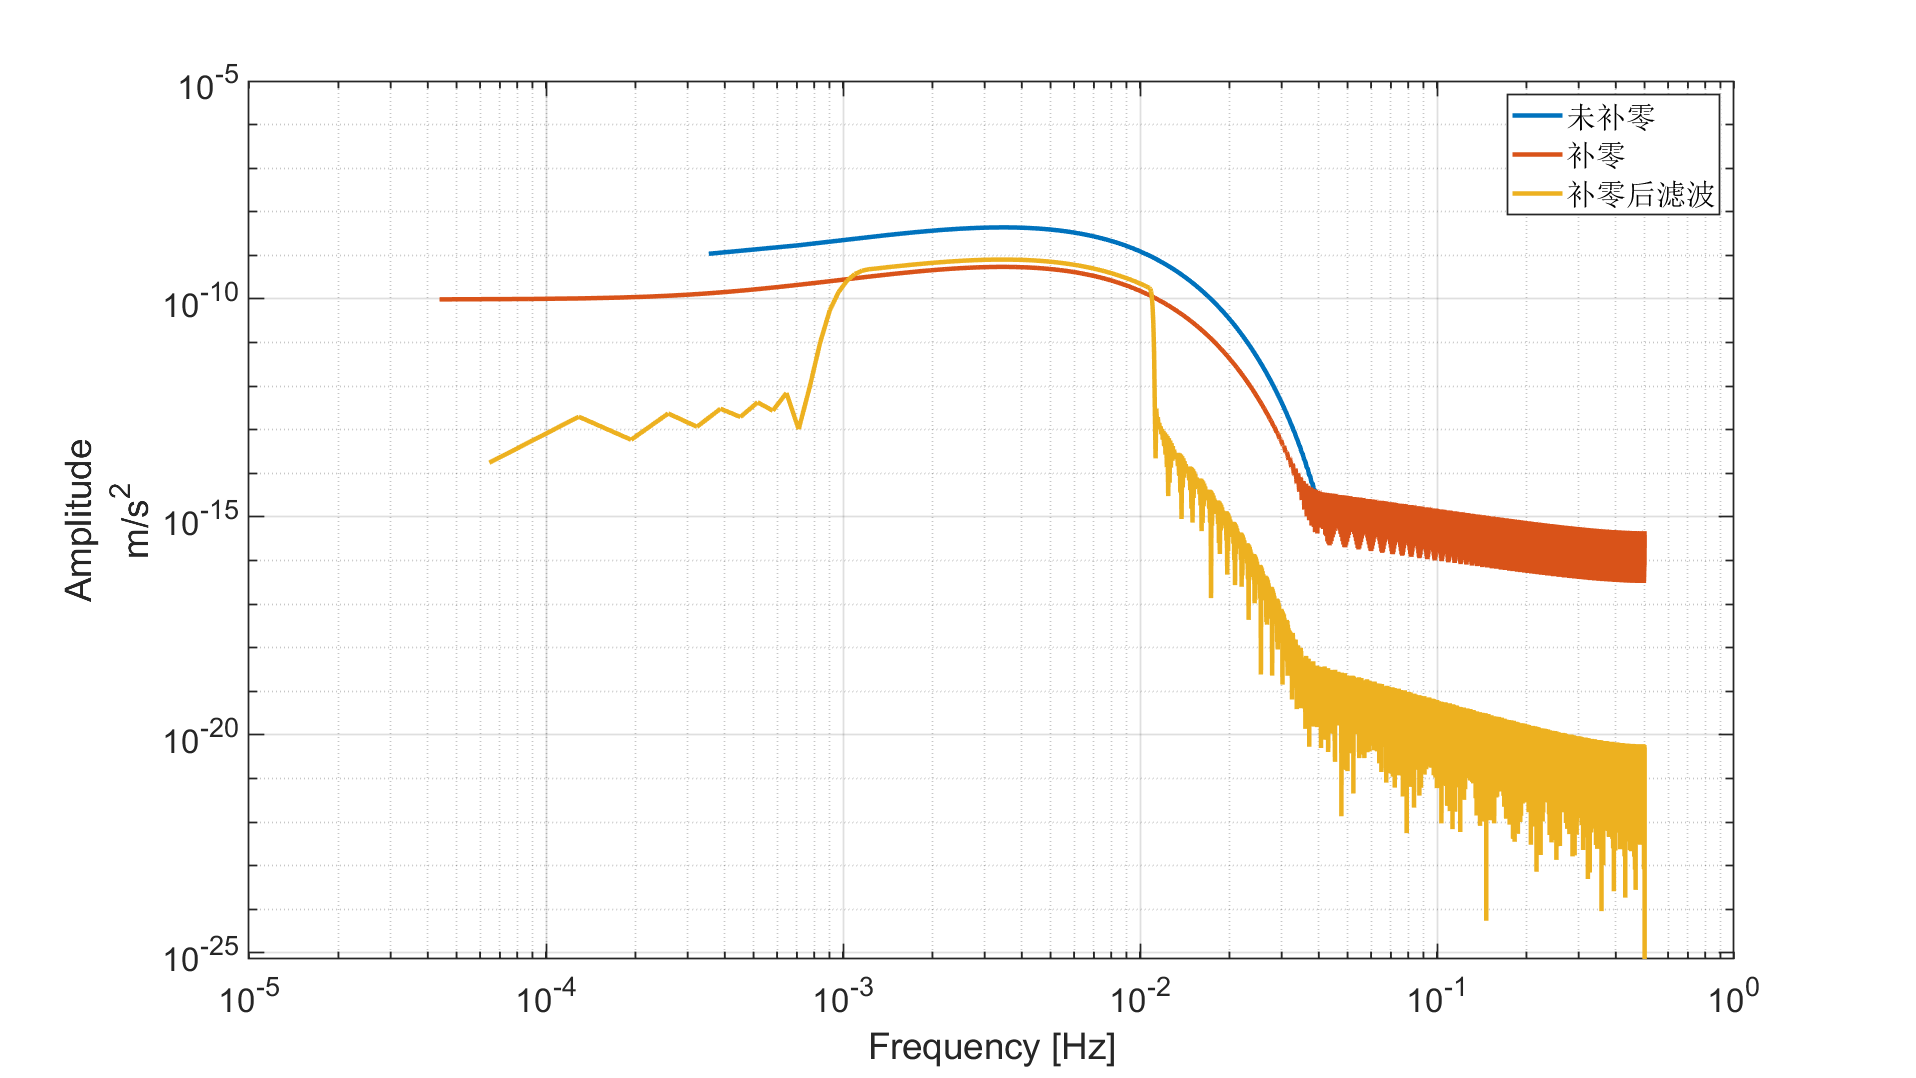

fft_plot(lgd_filtered, 1, "m/s^2"); hold on;
legend(["未补零", "补零", "补零后滤波"])

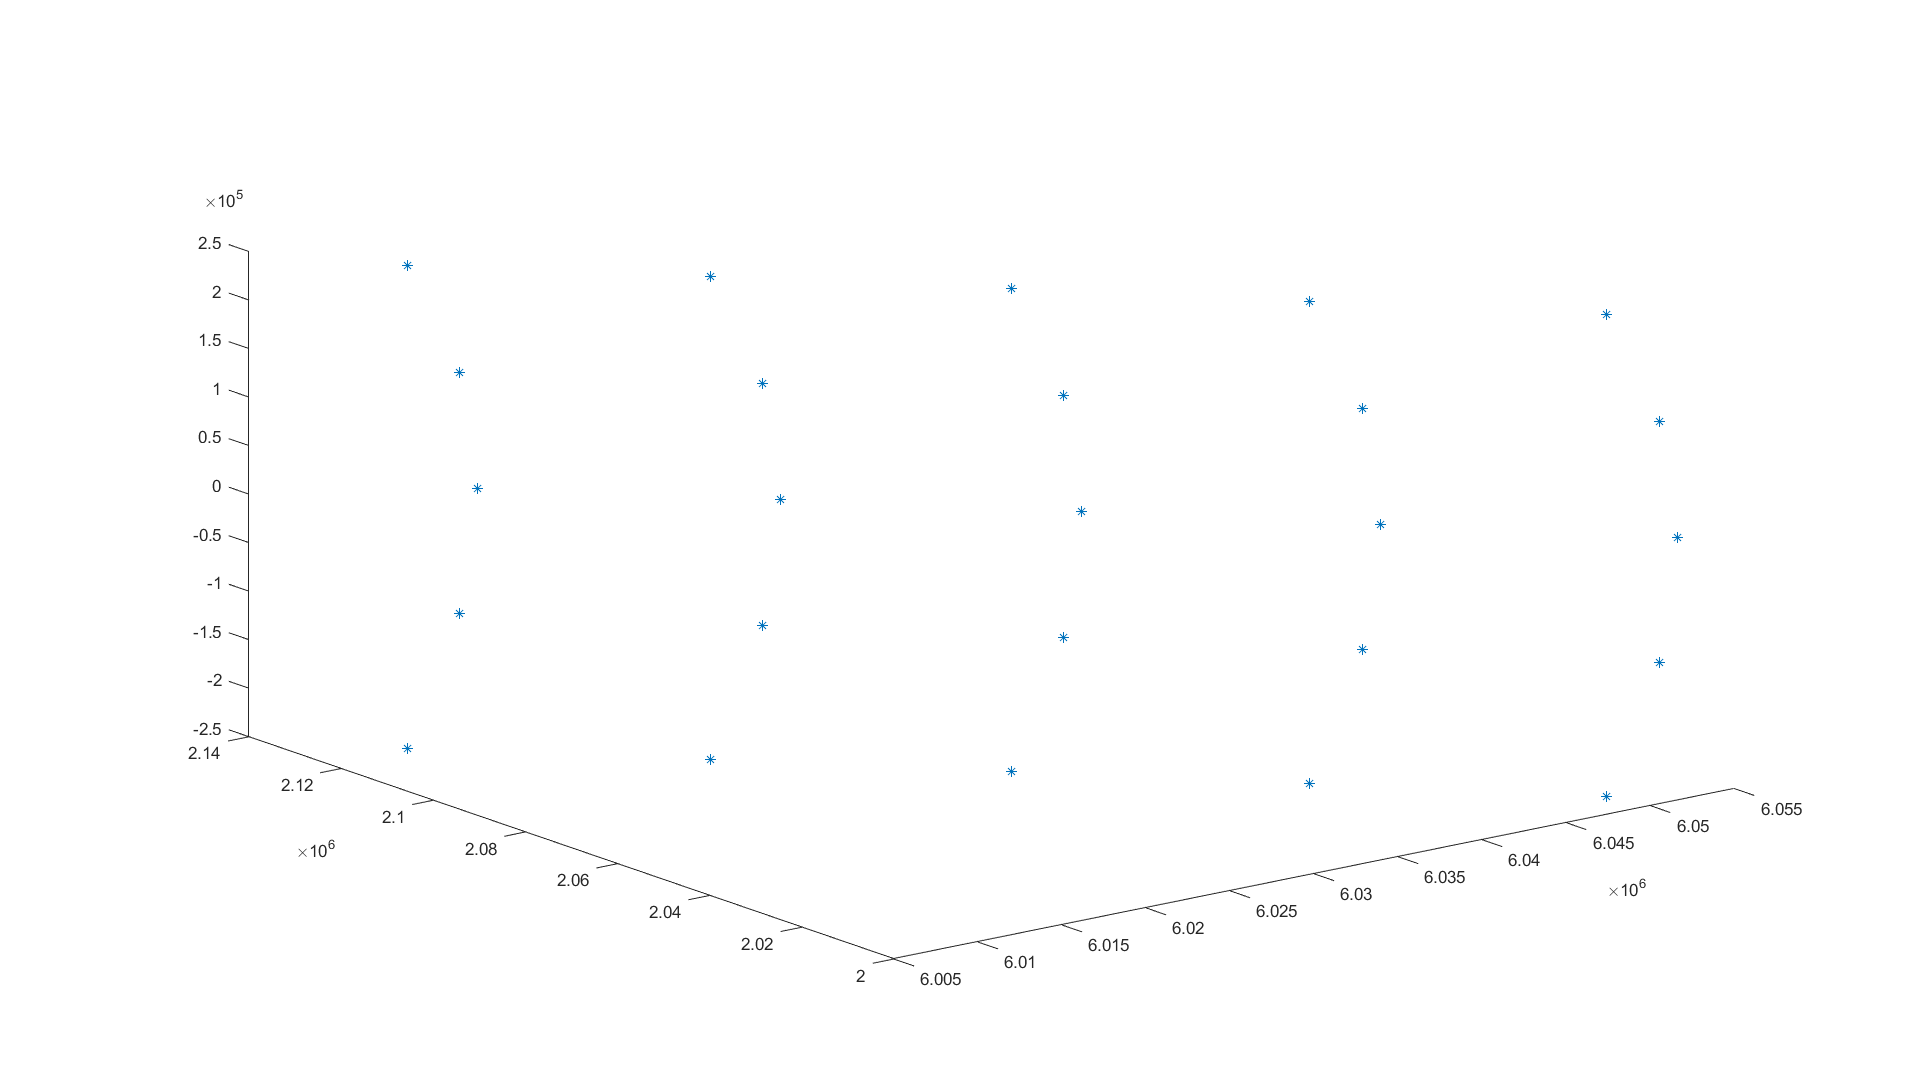



new_figure;
plot3(s_coor(:, 1), s_coor(:, 2), s_coor(:, 3), "*"); hold on

% plot3(coor_sate1(:, 1), coor_sate1(:, 2), coor_sate1(:, 3))
% axis equal